# Op-Amp with Capacitor

- *Electric Circuits Virtual Labs *

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

## Introduction

Operational amplifier can be configured to perform calculus operations such as differentiation and integration.  In an integrating circuit, the output is the integration of the input voltage with respect to time. An integrator circuit, which consists of active devices is called an Active Integrator. An active integrator provides a much lower output resistance and higher output voltage than it is possible with a simple RC circuit. Op-amp differentiating and integrating circuits are basically inverting amplifiers, with appropriately placed capacitors. The ideal Op-Amp integrator uses an inverting amplifier that has a capacitor in the feedback path. The output voltage is proportional to the negative integral (running sum) of the input voltage.  The ideal Op-Amp differentiator uses an inverting amplifier that has a capacitor in the input path. The output voltage is proportional to the negative rate of change of the input voltage.

## Learning Objectives

- Be able to design, set up, and simulate an integrator and differentiator circuit using op-amp.

## Operational Amplifier Integrator  

An Op-Amp integrator produces an output, which is an integral of the input voltage applied to its inverting terminal.  An ideal op-amp integrator uses a capacitor C, connected between the output and the op-amp inverting input terminal , as shown in example circuit.

Integrating circuits are most commonly used in analogue-to-digital converters, ramp generators and also in wave shaping applications.

#### Example 1. Op-Amp Integrator

Consider the following integator Op-Amp circuit.  No energy is stored in the capaction  at  t=0 $V(0)=V_0$ and the input signal is rectangular form with $V= \pm1V$, period is $T=2ms$, and pulse width $PW=1ms$.  Find and plot the output voltage $v_0(t)$ for $0 \le t \le 5ms$.  Simulate the circuit in Simulink to verify our results. 

                    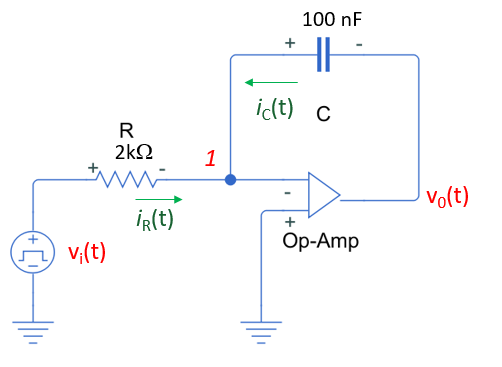       

Given values in the circuit

% Given Values in the circuit
R = 2e3;
C = 100e-9;
V0 = 0;  %initial capacitor voltage  at t=0

Lets plot the input voltage $v_i(t)$for $0 \le t \le 5ms$

figure ()
V = 1;
t = 0:0.0001:0.004;
x = V*square(2*pi*500*t,50);
stairs (t,x)

For $0 \le t \le 1ms$,   writing KCL at  Node 1 in the circuit

            
$$i_R(t)=i_C(t)$$


These currrents can be calculated as 

            $i_R(t)=\frac{v_s(t)-0}{R}$   and    $i_C(t)=-C\frac{dv_0(t)-0}{dt}$

where the voltage at the inverting input terminal of op-amp will be equal to the voltage present at its noninverting input terminal. So, the voltage at the inverting input terminal of opamp will be zero volts.

Substituting these two equations in the node equation, we obtain 

            $\frac{v_s(t)}{R}=-C\frac{dv_0(t)}{dt}$ ,   $dv_0(t)= -\frac{1}{RC}v_s(t)dt$ ,    

Take integral of both side

                
$$v_0(t)-v_0(0) = -\frac{1}{RC}\int _0^tv_s(\tau)d\tau$$
    

Then, $v_0(t)$is calculated as      

                
$$v_0(t)= -\frac{1}{RC}\int _0^tv_s(\tau)d\tau+v_0(0) $$


If the initial value of capacior is $v_0(0)=0$

                
$$v_0(t)= -\frac{1}{RC}\int _0^tv_s(\tau)d\tau$$


The output voltage, $v_0(t)$ is having a negative sign, which indicates that there exists 180 degree phase difference between the input and the output.

syms vi(t) v0(t) t t0
vi(t) = 1;
v0(t) = -1/(R*C)*int (vi(t),  0, t)

$$v0(t) = -5000\,t$$

Ploting $v_0(t) $for $0 \le t \le 1ms$

hold on
fplot(v0(t),[0.0 0.001],'r')

`Calculate the final integral value at `$t_0=1ms$

V0 = -1/(R*C)*int (vi(t),  0, 1e-3)

$$V0 = -5$$

Lets calculate $v_0(t) $ for $1ms \le t \le 2ms$,

vi(t) = -1;
t0 = 1e-3;
v0(t) = -1/(R*C)*int (vi(t),  t0, t)+V0

$$v0(t) = 5000\,t-10$$

Ploting  $v_0(t) $ 

fplot(v0(t),[0.001 0.002],'r')

`Calculate the final integral value at `$t_0=2ms$

V0 = -1/(R*C)*int (vi(t),  1e-3, 2e-3)+V0

$$V0 = 0$$

Lets calculate $v_0(t) $ for  $2ms \le t \le 3ms$,

vi(t) = 1;
t0 = 2e-3;
v0(t) = -1/(R*C)*int (vi(t),  t0, t)+V0

$$v0(t) = 10-5000\,t$$

Ploting$v_0(t) $ 

fplot(v0(t),[0.002 0.003],'r')

`Calculate the final integral value at `$t_0=3ms$

V0 = -1/(R*C)*int (vi(t),  2e-3, 3e-3)+V0

$$V0 = -5$$

For $3ms \le t \le 4ms$,

vi(t) = -1;
t0 = 3e-3;
v0(t) = -1/(R*C)*int (vi(t),  t0, t)+V0

$$v0(t) = 5000\,t-20$$

Ploting$v_0(t) $ 

fplot(v0(t),[0.003 0.004],'r')
axis([0 4e-3 -5 2])

`Calculate the final integral value at `$t_0=4ms$

V0 = -1/(R*C)*int (vi(t),  3e-3, 4e-3)+V0

$$V0 = 0$$

For $4ms \le t \le 5ms$,

vi(t) = -1;
t0 = 4e-3;
v0(t) = -1/(R*C)*int (vi(t),  t0, t)+V0

$$v0(t) = 5000\,t-20$$

Ploting$v_0(t) $ 

fplot(v0(t),[0.004 0.005],'r')

Set axis limits and label of the figure

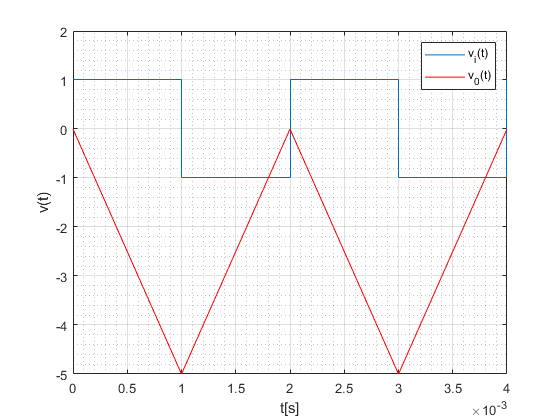

axis([0 4e-3 -5 2])
legend ('v_i(t)', 'v_0(t)')
grid on
grid minor
xlabel('t[s]')
ylabel('v(t)')

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_1.slx](matlab:open('./Simulink\Example_1.slx'))

            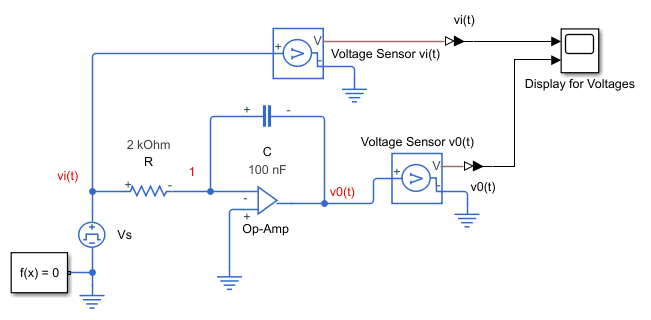

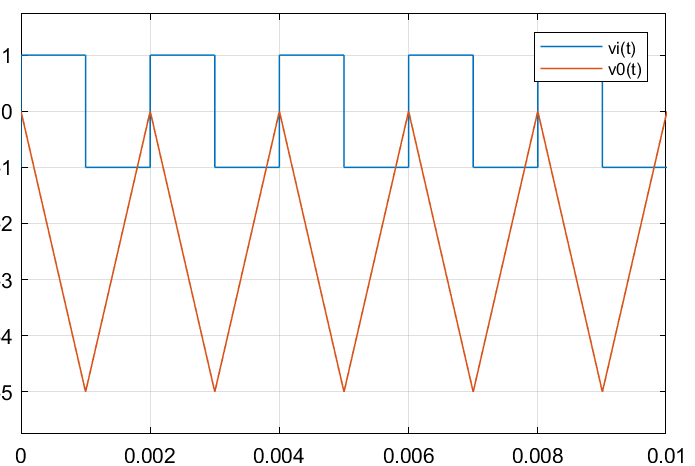

#### Exercise  1. Op-Amp Integrator 

Consider the following integator Op-Amp circuit.  No energy is stored in the capaction  at  t=0 $V(0)=V_0$ and the input signal is rectangular form with $V= \mp1V$, period is $T=4ms$, and pulse width $PW=2ms$ as given in following figure.  Find the output voltage $v_0(t)$and plot it for $0 \le t \le 8ms$. Simulate the circuit in Simulink to verify our results. 

                            

    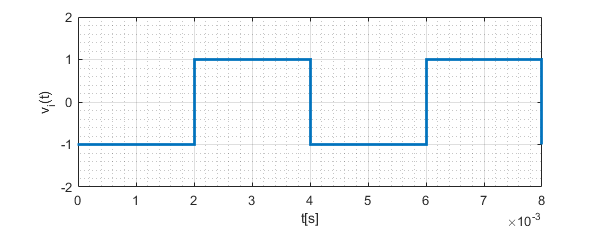

 **Solution**

Given values in the circuit

% Given Values in the circuit
% R = ?;
% C = ?;
% V0 = ?;  %initial capacitor voltage  at t=0

First, plot the input voltage $v_i(t)$for $0 \le t \le 8ms$

% figure ()
% V = -1;
% t = 0:0.0001:0.008;
% x = V*square(2*pi*25*t,50);
% stairs (t,x

For $0 \le t \le 2ms$,   the initial voltage across the capacitor is $v_0(0)=V_0$=0.  Write  KCL at  Node 1 in the circuit to find $v_0(t)$

% syms vi(t) v0(t) t t0
% vi(t) = ?;
% v0(t) = ?

Plot $v_0(t) $for $0 \le t \le 2ms$

% hold on
% fplot(?)

`Calculate the final integral value at `$t_0=2ms$

% V0 = ?

Calculate $v_0(t) $ for $2ms \le t \le 4ms$,

% vi(t) = ?;
% t0 = ?;
% v0(t) = ?

Plot  $v_0(t) $ 

% fplot(?)

`Calculate the final integral value at `$t_0=4ms$

% V0 = ?

Calculate $v_0(t) $ for  $4ms \le t \le 6ms$,

% vi(t) = ?;
% t0 = ?;
% v0(t) = ?

Plot$v_0(t) $ 

% fplot(?)

`Calculate the final integral value at `$t_0=6ms$

% V0 = ?

For $6ms \le t \le 8ms$,

% vi(t) = ? ;
% t0 = ? ;
% v0(t) = ?

Plot $v_0(t) $ 

% fplot(?)

Set axis limits and label of the figure

% axis([? ? ? ?])
% legend ('v_i(t)', 'v_0(t)')
% grid on
% grid minor
% xlabel('t[s]')
% ylabel('v(t)')

Simulate the circuit  in MATLAB Simulink 

        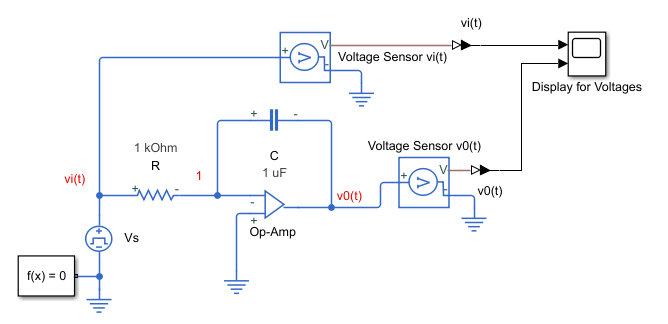

#### Example 2. Op-Amp Integrator

Consider the following integator Op-Amp circuit.  No energy is stored in the capaction  at  t=0 $V(0)=V_0$ and the input signal is rectangular form with $V= \pm1V$, period is $T=2ms$, and pulse width $PW=1ms$.  Find and plot the output voltage $v_0(t)$ for $0 \le t \le 5ms$.  Simulate the circuit in Simulink to verify our results. 

                    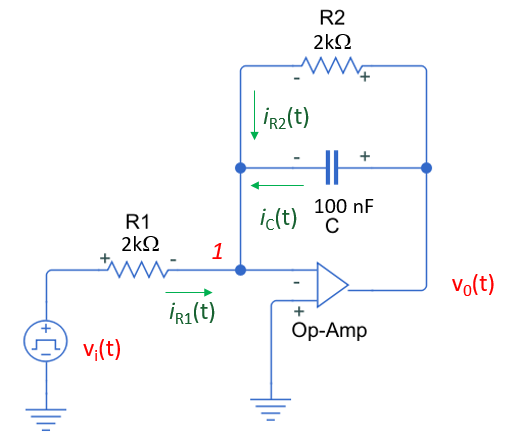       

Writing KCL at  Node 1 in the circuit

            
$$i_{R1}(t)+i_C(t)+i_{R2}(t)=0$$


The currrents can be calculated as 

            $i_{R1}(t)=\frac{v_i(t)-0}{R_1}$  $i_C(t)=C\frac{dv_0(t)-0}{dt}$ and  $i_{R2}(t)=\frac{v_0(t)-0}{R_2}$   

where  the voltage at the inverting input terminal of opamp is zero volts.

Substituting these two equations in the node equation, we obtain 

            
$$\frac{v_i(t)}{R_1}+C\frac{dv_0(t)}{dt}+\frac{v_0(t)}{R_2}=0$$
 

 Simplify as

         
$$\frac{dv_0(t)}{dt}+\frac{1}{R_2C}v_0(t)=-\frac{1}{R_1C}v_i(t)$$


   And

        $\frac{dv_0(t)}{dt}+a_0v_0(t)=-b_0v_i(t)$, where   $a_0=\frac{1}{R_2C}$ and $b_0=\frac{1}{R_1C}$

THis differential equation can be solved by  "dsolve" function  in  MATLAB 

Given values in the circuit

% Given Values in the circuit
figure ()
R1 = 2e3;
R2 = 2e3;
C = 100e-9;
V0 = 0;

We can express the input voltage $v_i(t) $for $0 \le t \le 5ms$ as


$$v _ i(t) = \left\{ \begin{array} { l l } { 1 } & { 0 \le t  \le 1 ms } \\  { -1 } & {1  \le t  \le 2 ms } \\  { 1} & { 2  \le t  \le 3 ms } \\  {-1} & {3 \le t  \le 4 ms } \\ { 1 } & { 4 \le t  \le 5 ms } \end{array} \right.$$


Lets plot the input voltage $v_i(t)$for $0 \le t \le 5ms$

V=1;
t=0:0.0001:0.005;
x=V*square(2*pi*500*t,50);
stairs (t,x)

For $0\le t \le 1ms$,

syms vi(t) v0(t) t t0
vi(t) = 1;
a0 = 1/(R2*C); b0=1/(R1*C);

eq = diff(v0(t))+a0*v0(t) == - b0*vi(t) 

$$eq = \frac{\partial }{\partial t}v_{0}\left(t\right)+5000\,v_{0}\left(t\right)=-5000$$

cond = [v0(0) == 0]

$$cond = v_{0}\left(0\right)=0$$

v0(t) = dsolve(eq, cond)

$$v0(t) = {\mathrm{e}}^{-5000\,t}-1$$

Ploting

hold on
fplot(v0(t),[0.0 0.001],'r')

Find the final value at $t=1ms$

t0=1e-3;
V0=v0(t0)

$$V0 = {\mathrm{e}}^{-5}-1$$

V0=vpa(V0,5)

$$V0 = -0.99326$$

For $1ms \le t \le 2ms$,

syms vi(t) v0(t) t t0

t0=1e-3;
vi(t)=-1;
eq = diff(v0(t))+a0*v0(t) == - b0*vi(t) 

$$eq = \frac{\partial }{\partial t}v_{0}\left(t\right)+5000\,v_{0}\left(t\right)=5000$$

cond = [v0(0) == V0]

$$cond = v_{0}\left(0\right)=-0.993262$$

v0(t) = dsolve(eq, cond)

$$v0(t) = 1-1.99326\,{\mathrm{e}}^{-5000\,t}$$

v0(t)=v0(t-t0)

$$v0(t) = 1-1.99326\,{\mathrm{e}}^{5-5000\,t}$$

Ploting

  fplot(v0(t),[0.001 0.002],'r')

Find the final value at $t=2ms$

t0=2e-3;
V0=v0(t0)

$$V0 = 1-1.99326\,{\mathrm{e}}^{-5}$$

V0=vpa(V0,5)

$$V0 = 0.98657$$

For $2ms \le t \le 3ms$,

syms vi(t) v0(t) t t0

t0=2e-3;
vi(t)=1;
eq = diff(v0(t))+a0*v0(t) == - b0*vi(t) 

$$eq = \frac{\partial }{\partial t}v_{0}\left(t\right)+5000\,v_{0}\left(t\right)=-5000$$

cond = [v0(0) == V0]

$$cond = v_{0}\left(0\right)=0.98657$$

v0(t) = dsolve(eq, cond)

$$v0(t) = 1.98657\,{\mathrm{e}}^{-5000\,t}-1$$

v0(t)=v0(t-t0)

$$v0(t) = 1.98657\,{\mathrm{e}}^{10-5000\,t}-1$$

Ploting

  fplot(v0(t),[0.002 0.003],'r')

Find the final value at $t = 3ms$

t0=3e-3;
V0=v0(t0)

$$V0 = 1.98657\,{\mathrm{e}}^{-5}-1$$

V0=vpa(V0,5)

$$V0 = -0.98661$$

For $3ms \le t \le 4ms$,

syms vi(t) v0(t) t t0

t0=3e-3;
vi(t)=-1;
eq = diff(v0(t))+a0*v0(t) == - b0*vi(t) 

$$eq = \frac{\partial }{\partial t}v_{0}\left(t\right)+5000\,v_{0}\left(t\right)=5000$$

cond = [v0(0) == V0]

$$cond = v_{0}\left(0\right)=-0.986615$$

v0(t) = dsolve(eq, cond)

$$v0(t) = 1-1.98661\,{\mathrm{e}}^{-5000\,t}$$

v0(t)=v0(t-t0)

$$v0(t) = 1-1.98661\,{\mathrm{e}}^{15-5000\,t}$$

Ploting

  fplot(v0(t),[0.003 0.004],'r')
  

Find the final value at $t = 4ms$

t0=4e-3;
V0=v0(t0)

$$V0 = 1-1.98661\,{\mathrm{e}}^{-5}$$

V0=vpa(V0,5)

$$V0 = 0.98661$$

For $4ms \le t \le 5ms$,

syms vi(t) v0(t) t t0

t0=4e-3;
vi(t)=1;
eq = diff(v0(t))+a0*v0(t) == - b0*vi(t) 

$$eq = \frac{\partial }{\partial t}v_{0}\left(t\right)+5000\,v_{0}\left(t\right)=-5000$$

cond = [v0(0) == V0]

$$cond = v_{0}\left(0\right)=0.986614$$

v0(t) = dsolve(eq, cond)

$$v0(t) = 1.98661\,{\mathrm{e}}^{-5000\,t}-1$$

v0(t)=v0(t-t0)

$$v0(t) = 1.98661\,{\mathrm{e}}^{20-5000\,t}-1$$

Ploting

  fplot(v0(t),[0.004 0.005],'r')

Set axis limits and label of the figure

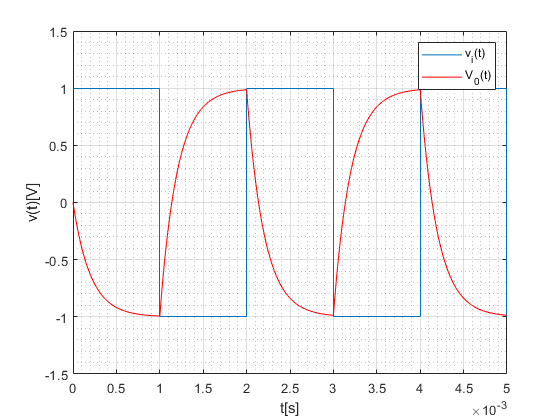

grid on
grid minor
xlabel('t[s]')
ylabel('v(t)[V]')
legend ('v_i(t)', 'V_0(t)')
axis([0 5e-3 -1.5 1.5])

 Circuit can be simulated  in MATLAB Simulink.[./Simulink\Example_2.slx](matlab:open('./Simulink\Example_2.slx'))

### 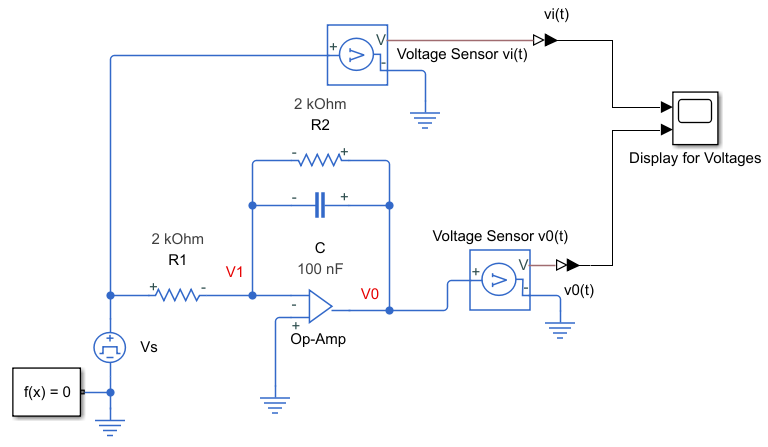

        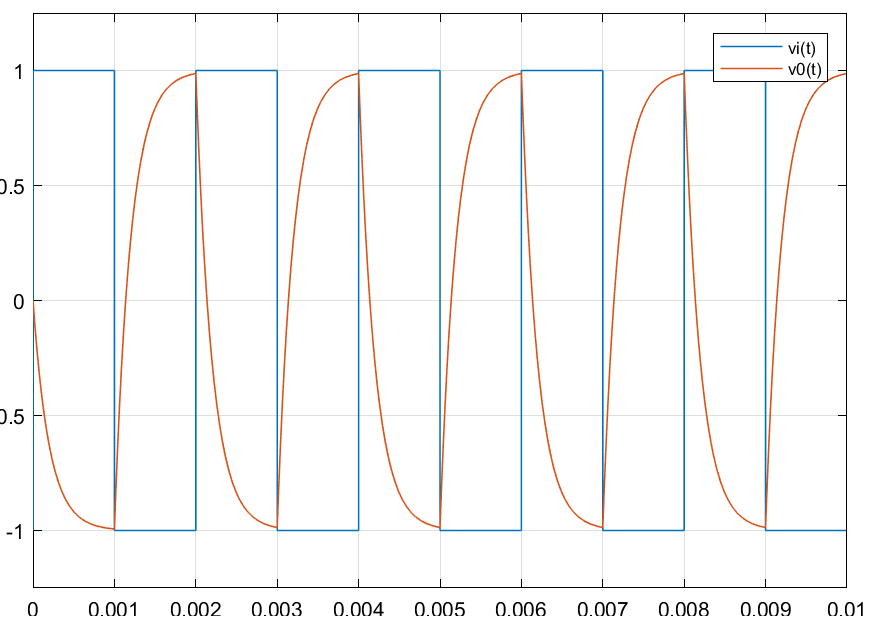

#### Exercise  2. Op-Amp Integrator 

Consider the following integator Op-Amp circuit.  No energy is stored in the capaction  at  t=0 $V(0)=V_0$ and the input signal is rectangular form with $V= \mp2 V$, period is $T=2ms$, and pulse width $PW=1ms$.  Find and plot the output voltage $v_0(t)$ for $0 \le t \le 5ms$.  Simulate the circuit in Simulink to verify our results. 

                    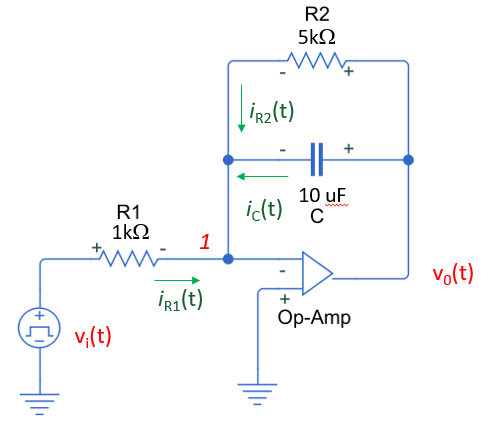

    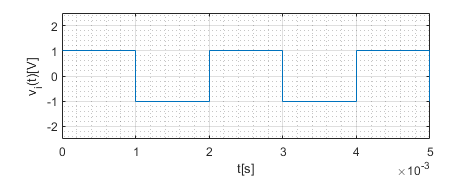

 **Solution**

Given values in the circuit

% Given Values in the circuit
% R1 = ?;
% R2 = ?;
% C = ?;
% V0 = ?;  %initial capacitor voltage  at t=0

First, plot the input voltage $v_i(t)$for $0 \le t \le 8ms$

% figure ()
% V = -1;
% t = 0:0.0001:0.008;
% x = V*square(2*pi*25*t,50);
% stairs (t,x

For $0 \le t \le1ms$,   the initial voltage across the capacitor is $v_0(0)=V_0$=0.  Write  KCL at  Node 1 in the circuit to find $v_0(t)$

% syms vi(t) v0(t) t t0
% vi(t) = ?;
% v0(t) = ?

Plot $v_0(t) $for $0 \le t \le1ms$

% hold on
% fplot(?)

`Calculate the final integral value at `$t_0=1ms$

% V0 = ?

Calculate $v_0(t) $ for $1ms \le t \le 2ms$,

% vi(t) = ?;
% t0 = ?;
% v0(t) = ?

Plot  $v_0(t) $ 

% fplot(?)

`Calculate the final integral value at `$t_0=2ms$

% V0 = ?

Calculate $v_0(t) $ for  $2ms \le t \le 3ms$,

% vi(t) = ?;
% t0 = ?;
% v0(t) = ?

Plot$v_0(t) $ 

% fplot(?)

`Calculate the final integral value at `$t_0=3ms$

% V0 = ?

For $3ms \le t \le 4ms$,

% vi(t) = ? ;
% t0 = ? ;
% v0(t) = ?

Plot $v_0(t) $ 

% fplot(?)

Set axis limits and label of the figure

% axis([? ? ? ?])
% legend ('v_i(t)', 'v_0(t)')
% grid on
% grid minor
% xlabel('t[s]')
% ylabel('v(t)')

Simulate the circuit  in MATLAB Simulink 

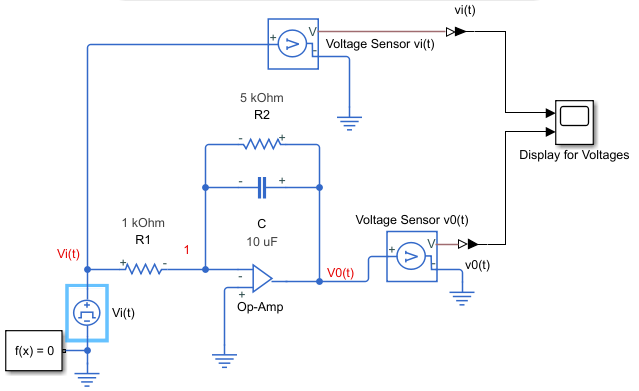

## Operational Amplifier Differentiator

An op-amp differentiator or a differentiator amplifier is a circuit configuration which is inverse of the integrator circuit. It produces an output signal, which is the first order derivative of the input signal. An op-amp differentiator is an inverting amplifier that uses a capacitor in series with the input voltage. Differentiating circuits are usually designed to respond for triangular and rectangular input waveforms.

Consider the following integator Op-Amp circuit. 

            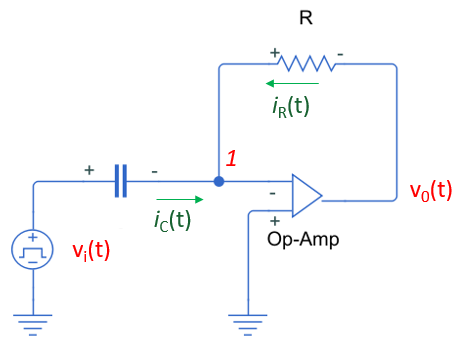

 Writing KCL at  Node 1 in the circuit

            
$$i_C(t)+i_R(t)=0$$


The currrents can be calculated as 

              $i_C(t)=C\frac{dv_i(t)-0}{dt}$ and  $i_R(t)=\frac{v_0(t)-0}{R}$   

where the voltage at the inverting input terminal of op-amp will be equal to the voltage present at its noninverting input terminal. So, the voltage at the inverting input terminal of opamp will be zero volts.

Substituting these two equations in the node equation, we obtain 

            
$$C\frac{dv_i(t)}{dt}+\frac{v_0(t)}{R}=0$$
 

 Solving for $v_0(t)$, we obtain

             $v_0(t)= -RC \frac{d v_i(t)}{dt}$ ,    

The output voltage, $v_0(t)$is the derivative of the input and having a negative sign, which indicates that there exists 180 degree phase difference between the input and the output.  This differentiator circuit can be unstable for any electrical noise within the circuit is exaggerated by the differentiator.  So, it is not popular as the integrator and is rarely used in practice

#### Example 3. Op-Amp Differentiator                   

Consider the following ideal Op-Amp differentiator circuit.  No energy is stored in the capaction  at  t=0 $V(0)=V_0$ and the input signal is triangle form with $V= \pm1V$, and period is $T=10ms$.  Find and plot the output voltage $v_0(t)$ for $0 \le t \le 25ms$.  Simulate the circuit in Simulink to verify our results. 

                    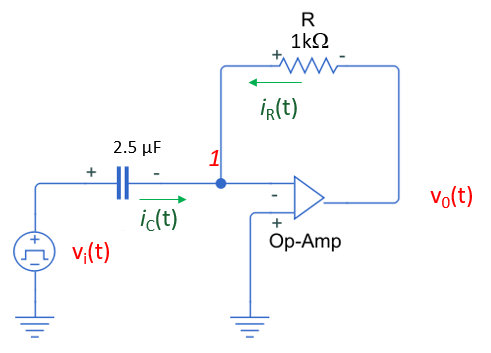       

Given values in the circuit

% Given Values in the circuit
R = 1e3;
C = 2.5e-6;
V0 = 0;  %initial capacitor voltage  at t=0

We can express the input voltage $v_i(t) $for $0 \le t \le 25ms$ as


$$v _ i(t) = \left\{ \begin{array} { l l } { 400 t } & { 0 \le t  \le5 ms } \\  { -400 t+4 } & { 5  \le t  \le 10 ms } \\  { 400 t -4} & { 10  \le t  \le 15 ms } \\  {-400 t +8} & {15  \le t  \le 20 ms } \\ { 400 t-8 } & { 20  \le t  \le 25ms } \end{array} \right.$$


Lets plot the input voltage $v_i(t)$for $0 \le t \le 25ms$

figure ()
V = 1;
t = 0:0.001:0.025;
vi = 1+V*sawtooth(2*pi*100*t,1/2);
plot (t,vi)

For $0 < t < 5ms$,    

     $v_0(t)= -RC \frac{d v_i(t)}{dt}$ ,    

syms vi(t) v0(t) t 
V = 2;
vi(t) = 400*t ;
v0(t) = -R*C*diff(vi,t)

$$v0(t) = -1$$

Ploting $v_0(t) $for $0< t < 5ms$

hold on
fplot(v0(t),[0.0 0.005],'r')

Lets calculate $v_0(t) $ for $5ms < t <10ms$,

vi(t) =-400*t+4 ;
v0(t) = -R*C*diff(vi,t)

$$v0(t) = 1$$

Ploting  $v_0(t) $ 

fplot(v0(t),[0.005 0.01],'r')

Lets calculate $v_0(t) $ for $10 ms< t <  15ms$

vi(t) =400*t-4 ;
v0(t) = -R*C*diff(vi,t)

$$v0(t) = -1$$

Ploting$v_0(t) $ 

fplot(v0(t),[0.01 0.015],'r')

For $15 ms< t <  20ms$,

vi(t) =-400*t+8 ;
v0(t) = -R*C*diff(vi,t)

$$v0(t) = 1$$

Ploting$v_0(t) $ 

fplot(v0(t),[0.015 0.02],'r')

For $20 ms< t< 25ms$,

vi(t) =400*t-8 ;
v0(t) = -R*C*diff(vi,t)

$$v0(t) = -1$$

Ploting$v_0(t) $ 

fplot(v0(t),[0.02 0.025],'r')

Set axis limits and label of the figure

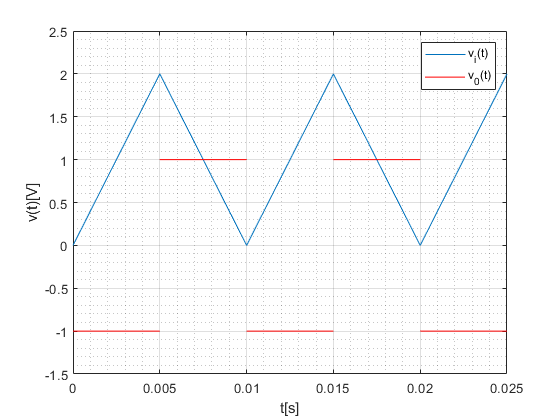

axis([0 25e-3 -1.5 2.5])
legend ('v_i(t)', 'v_0(t)')
grid on
grid minor
xlabel('t[s]')
ylabel('v(t)[V]')

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_3.slx](matlab:open('./Simulink\Example_3.slx'))

            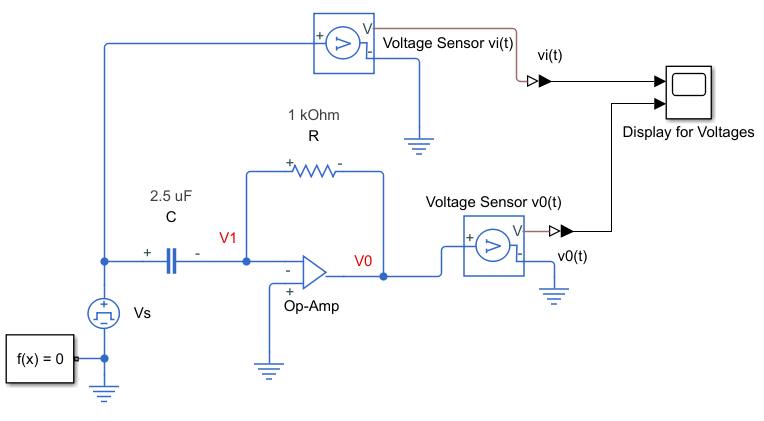

        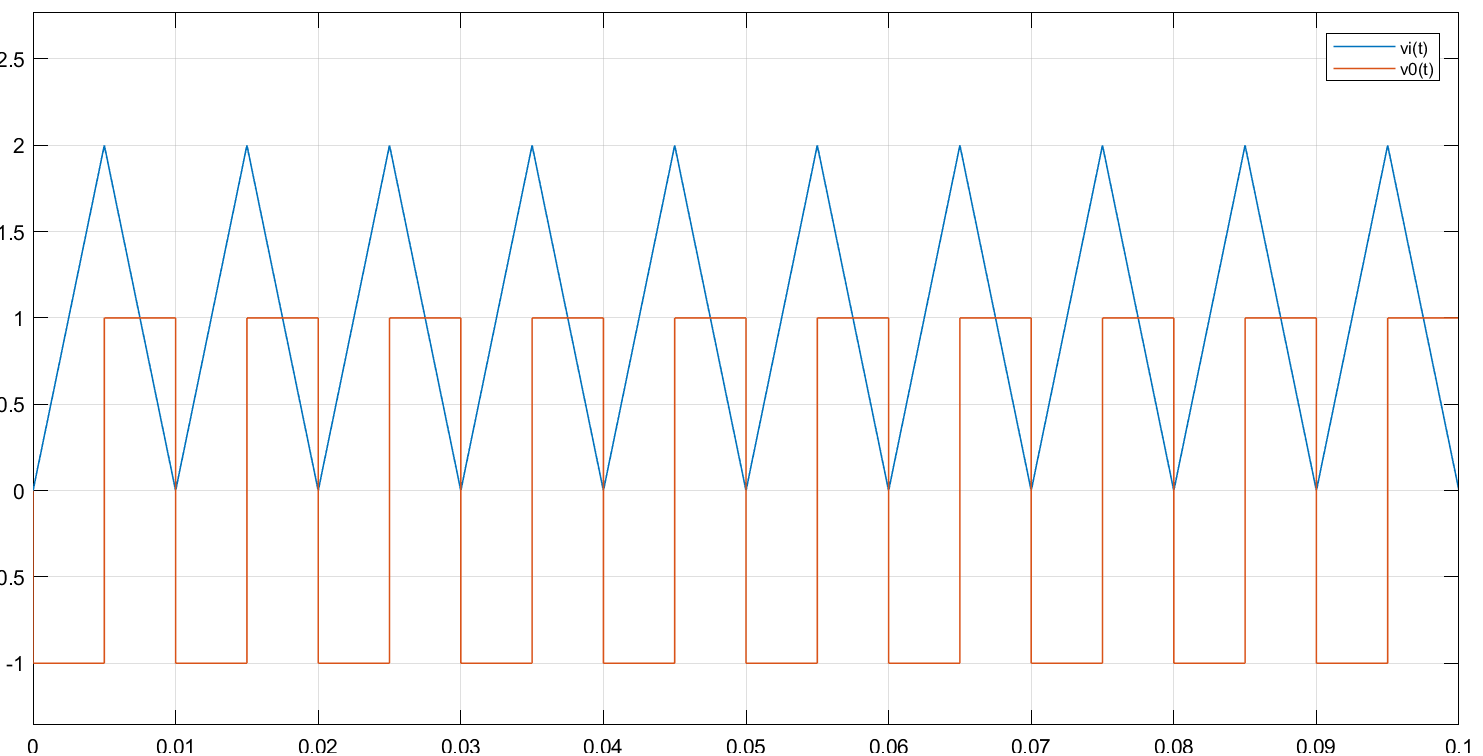

#### Exercise 3: Op-Amp Differentiator                   

Consider the following ideal Op-Amp differentiator circuit.  No energy is stored in the capaction  at  t=0 $V(0)=V_0$ and the input signal is triangle form folowing figure.  Find and plot the output voltage $v_0(t)$ for $0 \le t \le 0.04s$.  Simulate the circuit in Simulink to verify our results. 

                    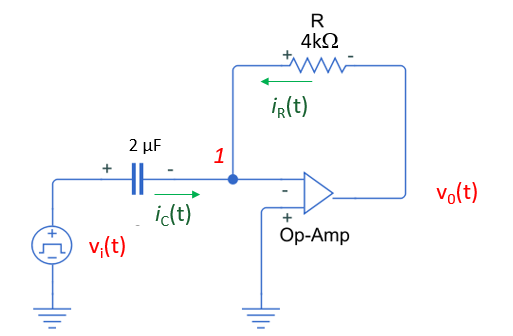       

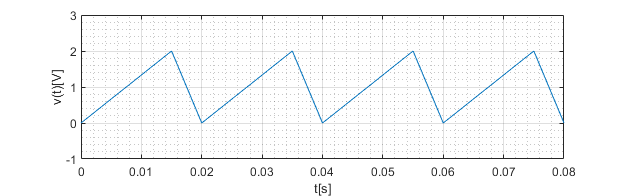

Given values in the circuit

% Given Values in the circuit
% R = ?;
% C = ?;
% V0 = ?;  %initial capacitor voltage  at t=0

Express the input voltage $v_i(t) $for $0 \le t \le 0.08s$ as

Lets plot the input voltage $v_i(t)$for $0 \le t \le 0.08s$

% figure ()
% V = ?;
% t = ?;
% vi = ?;
% plot (t,vi)

For $0 < t < 0.015s$,    

 Find     $v_0(t)$ ,    

% syms vi(t) v0(t) t 
% V = ?;
% vi(t) = ? ;
% v0(t) = ?

Plot $v_0(t) $for $0< t <0.015s$

% hold on
% fplot(v0(t),[? ?],'r')

Lets calculate $v_0(t) $ for $0.015s < t <0.02s$,

% vi(t) =? ;
% v0(t) = ?

Plot $v_0(t) $ 

% fplot(v0(t),[? ?],'r')

Lets calculate $v_0(t) $ for $0.02s< t <  0.035s$

% vi(t) =? ;
% v0(t) =?

Plot $v_0(t) $ 

% fplot(v0(t),[? ?],'r')

For $0.035s< t < 0.04s$,

% vi(t) =?;
% v0(t) = ?

Plot$v_0(t) $ 

% fplot(v0(t),[? ?],'r')

Set axis limits and label of the figure

% axis([? ? ? ?])
% legend ('v_i(t)', 'v_0(t)')
% grid on
% grid minor
% xlabel('t[s]')
% ylabel('v(t)[V]')

Simulate  this exercise using MATLAB Simulink to chek your values. 

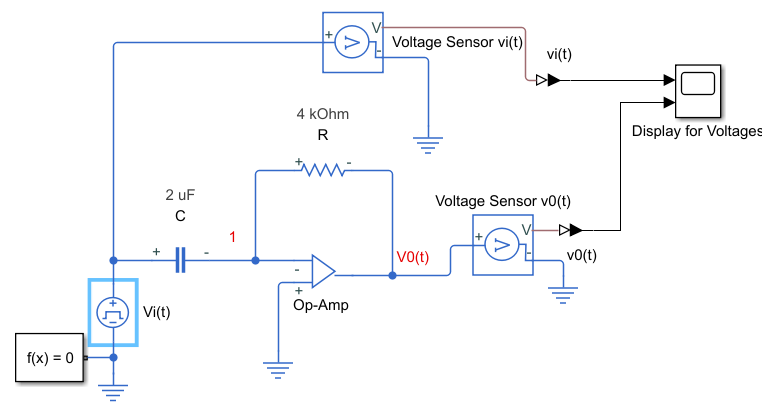

#### Example 4 Op-Amp Differentiator

Consider the following ideal Op-Amp differentiator circuit.  No energy is stored in the capaction  at  t=0 $V(0)=V_0$ and the input signal is triangle form with $V= \pm1V$, and period is $T=10ms$.  Find and plot the output voltage $v_0(t)$ for $0 \le t \le 25ms$.  Simulate the circuit in Simulink to verify our results. 

                           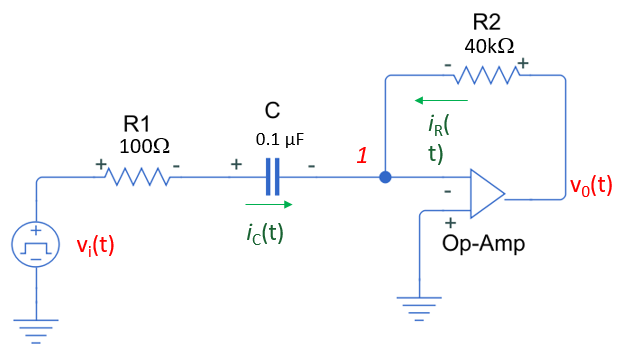

 Writing KCL at  Node 1 in the circuit

                
$$i_C(t)+i_R(t)=0$$


To find $i_C(t)$, we applying KVL

                
$$- V _ i(t) + R_1 i ( t ) + v_C( t ) = 0$$
               

The current i(t) through the capacitor is given by $i ( t ) = C \frac { d v ( t ) } { d t }$. Substitude the equation

          
$$- V _ i(t) + R_1 C \frac { d v_C ( t ) } { d t } + v_C ( t ) = 0$$


Dividing by R1C  and rearranging

            $\frac { d v_C( t ) } { d t } = - \frac { 1 } { R_1 C } [ v_C ( t ) - v _ i(t) ]$   one more step $\frac { d v_C ( t ) } { v_C( t ) - V _ i(t) } = - \frac { 1 } { R_1 C } d t$

Taking Integral both sides and simplifying the result. The final solution is given  by

          $v_C( t ) = v _i(t) + ( V _ { 0 } - v _ i(t) ) e ^ { - \frac { t } { R_1 C } }$ for $t\geq0$.  

At t = 0, the voltage is v(0) = V0, and at $t=\infty$, the voltage is $v(\infty)=V_s$.  The voltage across the capacitor changes from the initial value of $v(0)=V_0$ at t=0 to the final value of $v ( \infty ) = V_s$ at $t = \infty$.

The currrents can be calculated as 

              
$$i_C(t)=C\frac{dv_C(t)}{dt}=C\frac{d}{dt}\Big( v _i(t) + ( V_0 - v _ i(t) ) e ^ { - \frac { t } { R_1 C } } \Big)$$
 

            
$$i_C(t)=C\frac{d}{dt}\Big( v _i(t) + ( V_0 - v _ i(t) ) e ^ { - \frac { t } { R_1 C } } \Big)$$


        and  $i_R(t)=\frac{v_0(t)-0}{R_2}$   

where the voltage at the inverting input terminal of op-amp will be equal to the voltage present at its noninverting input terminal. So, the voltage at the inverting input terminal of opamp will be zero volts.

Substituting these two equations in the node equation, we obtain 

            
$$C\frac{d}{dt}\Big( v _i(t) + ( V _ { 0 } - v _ i(t) ) e ^ { - \frac { t } { R_1 C } } \Big)+\frac{v_0(t)}{R_2}=0$$
 

 Solving for $v_0(t)$, we obtain

             $v_0(t)= -R_2C \frac{d}{dt}\Big( v _i(t) + ( V_0- v_ i(t) ) e ^ { - \frac { t } { R_1 C } } \Big)$ ,    

Given values in the circuit

% Given Values in the circuit
R1 = 100;
C = 0.1e-6;
R2 = 40e3;
V0 = 0;  %initial capacitor voltage  at t=0

We can express the input voltage $v_i(t) $for $0 \le t \le 25ms$ as


$$v _ i(t) = \left\{ \begin{array} { l l } { 400 t } & { 0 \le t  \le5 ms } \\  { -400 t+4 } & { 5  \le t  \le 10 ms } \\  { 400 t -4} & { 10  \le t  \le 15 ms } \\  {-400 t +8} & {15  \le t  \le 20 ms } \\ { 400 t-8 } & { 20  \le t  \le 25ms } \end{array} \right.$$


Lets plot the input voltage $v_i(t)$for $0 \le t \le 25ms$

figure()
V = 1;
t = 0:0.001:0.025;
vi = 1+V*sawtooth(2*pi*100*t,1/2);
plot (t,vi)

For $0 < t < 5ms$,    

     $v_0(t)= -R_2C \frac{d}{dt}\Big( v _i(t) + ( V_0- v_ i(t) ) e ^ { - \frac { t } { R_1 C } } \Big)$ and $V_0=0$

syms vi(t) f(t) v0(t) t 
V = 0;
vi(t) = 400*t ;
%  f(t)=vi(t)+(V0-vi(t))*exp(-t/R1*C)
%  v0(t) = -R2*C*diff(f,t)
v0(t) = -R2*C*diff(vi,t)

$$v0(t) = -\frac{8}{5}$$

Ploting $v_0(t) $for $0< t < 5ms$

hold on
fplot(v0(t),[0.0 0.005],'r')

Lets calculate $v_0(t) $ for $5ms < t <10ms$,

vi(t) =-400*t+4 ;
v0(t) = -R2*C*diff(vi,t)

$$v0(t) = \frac{8}{5}$$

Ploting  $v_0(t) $ 

fplot(v0(t),[0.005 0.01],'r')

Lets calculate $v_0(t) $ for $10 ms< t <  15ms$

vi(t) =400*t-4 ;
v0(t) = -R2*C*diff(vi,t)

$$v0(t) = -\frac{8}{5}$$

Ploting$v_0(t) $ 

fplot(v0(t),[0.01 0.015],'r')

For $15 ms< t <  20ms$,

vi(t) =-400*t+8 ;
v0(t) = -R2*C*diff(vi,t)

$$v0(t) = \frac{8}{5}$$

Ploting$v_0(t) $ 

fplot(v0(t),[0.015 0.02],'r')

For $20 ms< t< 25ms$,

vi(t) =400*t-8 ;
v0(t) = -R2*C*diff(vi,t)

$$v0(t) = -\frac{8}{5}$$

Ploting$v_0(t) $ 

 fplot(v0(t),[0.02 0.025],'r')

Set axis limits and label of the figure

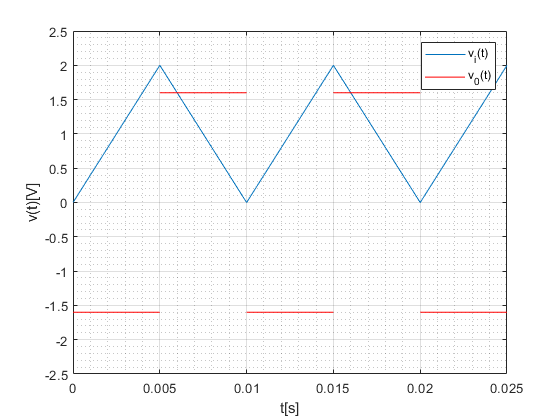

axis([0 25e-3 -2.5 2.5])
legend ('v_i(t)', 'v_0(t)')
grid on
grid minor
xlabel('t[s]')
ylabel('v(t)[V]')

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_4.slx](matlab:open('./Simulink\Example_4.slx'))

            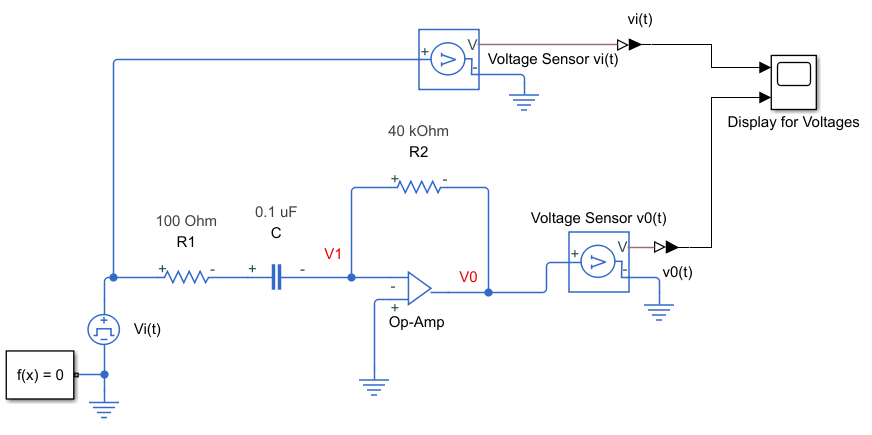

Sumilation results is given in next figure

        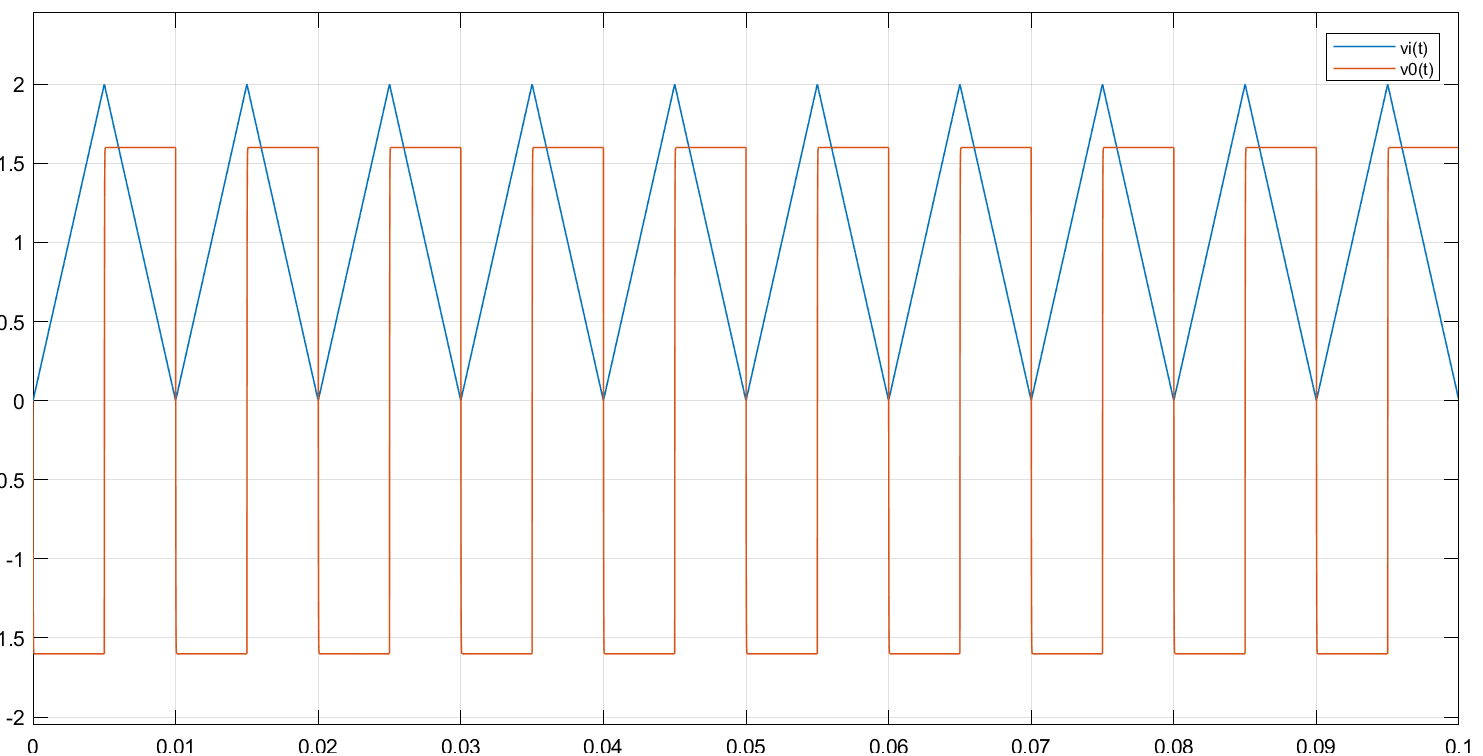

#### Exercise 4 : Op-Amp Differentiator

Consider the following ideal Op-Amp differentiator circuit.  No energy is stored in the capaction  at  t=0 $V(0)=V_0=4V$.  Find and plot the output voltage $v_0(t)$ for $0 \le t \le 0.8s$.  Simulate the circuit in Simulink to verify our results. 

                           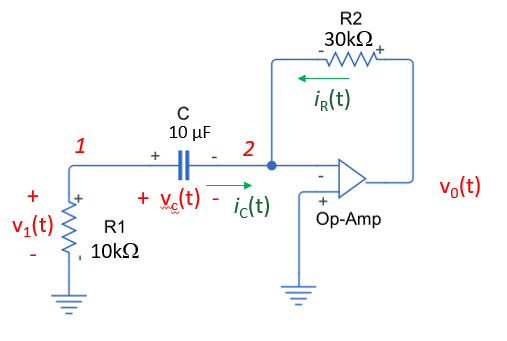

Apply KCL at  Node 1 in the circuit

Write each of the branch currents in terms of $v_1(t) $and $v_C(t)$

Since  the voltage at the inverting input terminal of opamp is zero volts, $v_C(t)=v_1(t)$

Simplify your equation and find $v_C(t)$ using initial value.

Apply KCL at  Node 2  in the circuit

Write each of the branch currents in terms of $v_C(t) $and $v_0(t)$

Find $v_0(t)$   as first derivative of v_C(t)

Given values in the circuit

% % Given Values in the circuit
% R1 = ?;
% C = ?;
% R2 = ?;
% V0 = 0? ;  %initial capacitor voltage  at t=0

Plot $v_1(t)$voltage for $0 \le t \le 0.8s$

% figure()
% t = 0:0.001:0.8;
% ???


Find $v_0(t) $

% syms vC(t) f(t) v0(t) t 
% vC(t) = ?? ;
% 
% v0(t) =??

Ploting $v_0(t) $for $0< t < 0.8s$

% hold on
% fplot(v0(t),[0.0 0.08],'r')

Simulate  this exercise using MATLAB Simulink to chek your values. 

### 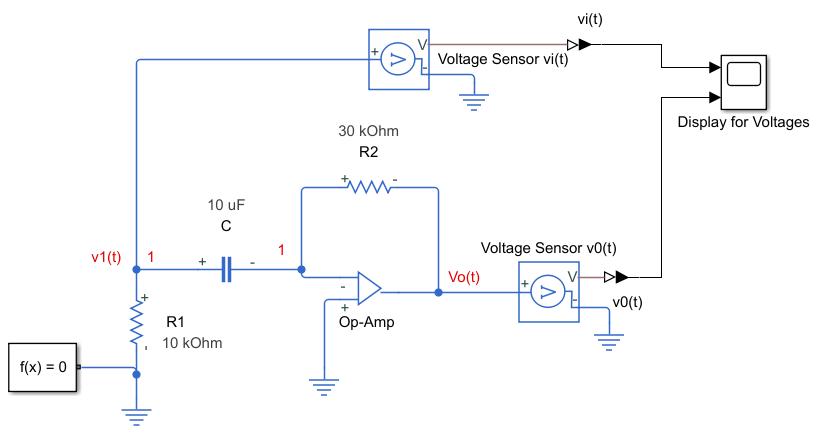

### References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018